# Evaluación 9 (Planeación de Trayectorias)

Bruno Manuel Zamora Garcia A01798275

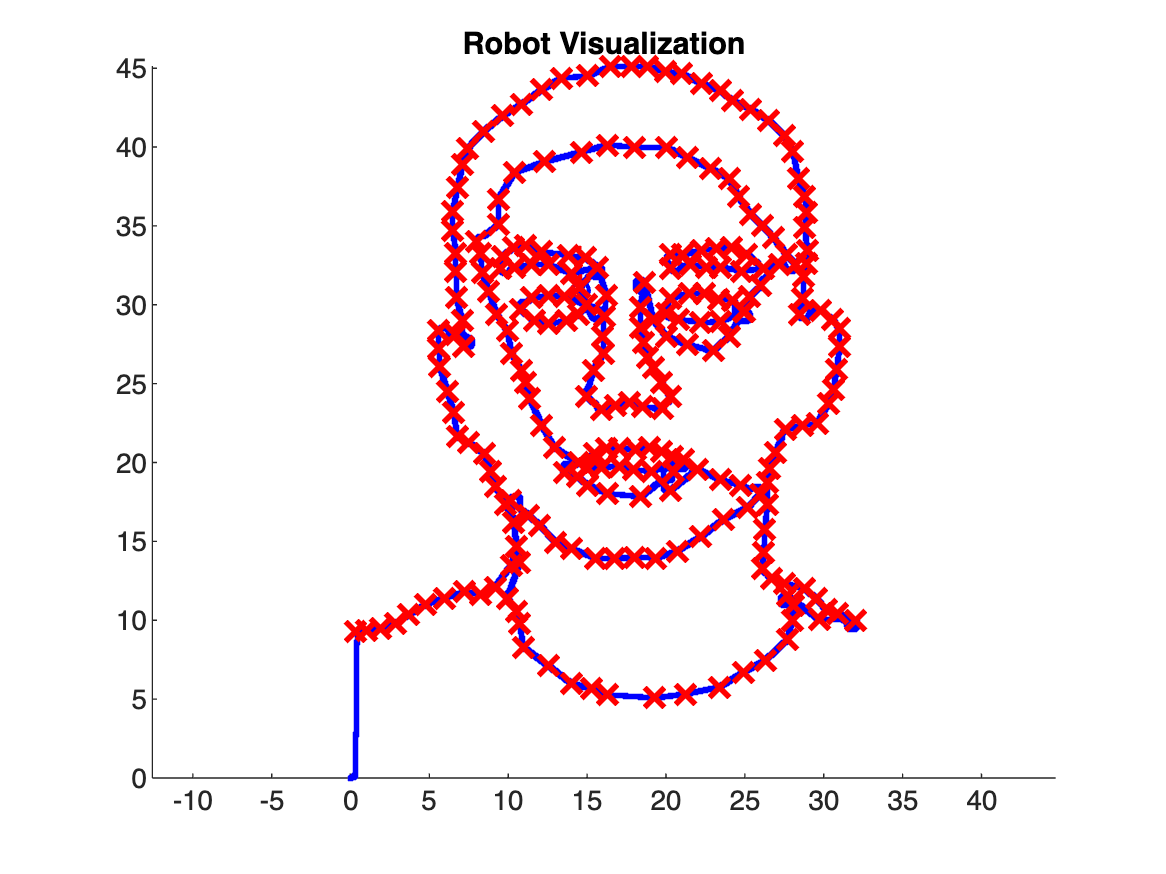

R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.005;               % Sample time [s]
tVec = 0:sampleTime:345;         % Time array

initPose = [0;0;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

%Define waypoints
waypoints = [
    % Imagen 0 (sin sufijo):
    0.3027416790635, 9.3116827505435;   % C
    1.0329072602468, 9.3603604559557;   % D
    1.9091059576667, 9.4577158667802;   % E
    2.8339823604988, 9.7984598046657;   % F
    3.6615033525065, 10.3339145642001;  % G
    4.7810905769876, 11.0154024399711;  % H
    5.9493555068808, 11.4048240832689;  % I
    7.2149758475984, 11.7942457265666;  % J
    8.2372076612550, 11.6482126103300;  % K
    9.1620840640871, 12.0863119590399;  % L
    10.1843158777437, 13.4979654159943; % M
    10.5250598156292, 14.6662303458875; % N
    10.3304899398040, 16.1752392136663; % O
    9.8435719398582, 17.3435041435595;  % P
    9.1620840640871, 18.5117690734527;  % Q
    8.8700178316138, 19.4366454762849;  % R
    8.4805961883161, 20.5562327007659;  % S
    7.4583643746595, 21.2863982819491;  % T
    6.7768764988885, 21.6271422198347;  % U
    6.5334879718274, 23.1848287930256;  % V
    6.1440663285297, 24.4991268391555;  % W
    5.6572892744075, 26.0568134123465;  % Z

    % Imagen 1 (sufijo 1):
    5.5999338635830, 27.2250783422397;  % A1
    5.5999338635830, 28.3446556672707;  % B1
    6.6795210880640, 28.1012770396596;  % C1
    7.1662981421862, 27.3711114584764;  % D1
    7.0689427313618, 29.0261534424918;  % E1
    6.7281987934763, 30.4378068994461;  % F1
    6.6795210880640, 32.1415265888737;  % G1
    6.6795210880640, 33.2611138133548;  % H1
    6.4848102664152, 34.7214449757213;  % I1
    6.4848102664152, 35.8897099056145;  % J1
    6.7768764988885, 37.4473964788055;  % K1
    7.1176204367740, 38.9077276411720;  % L1
    7.4096866924730, 39.8812817494164;  % M1
    8.4319184829039, 41.0008689783970;  % N1
    9.6488611182093, 41.9744230821418;  % O1
    10.8171260481026, 42.7045886332500; % P1
    12.1314240942324, 43.6294650661572; % Q1
    13.3483667295379, 44.3596306473404; % R1
    15.0034087135533, 44.5056637635771; % S1
    16.4637398759198, 45.0897962285237; % T1
    17.8267156274619, 45.1384739339359; % U1
    18.8002697357063, 45.1384739339359; % V1
    19.9685346655995, 44.7972999605040; % W1
    20.9907664792561, 44.6516968798183; % Z1

    % Imagen 2 (sufijo 2):
    22.2563868199737, 44.0188867094549; % A2
    23.4246517498669, 43.5807873607450; % B2
    24.2034950364624, 42.9479771903861; % C2
    25.3717599663556, 42.4125224308517; % D2
    26.4913471908367, 41.6823568496685; % E2
    27.5135790044932, 40.7088027414241; % F2
    28.0490337640276, 39.7352486331797; % G2
    28.3897777019131, 37.9828512383399; % H2
    28.7791993452109, 36.8632640138589; % I2
    28.9252324614475, 35.8410322002023; % J2
    28.7791993452109, 34.9161557973702; % K2
    28.9739101668598, 33.4558246350036; % L2
    28.9252324614475, 32.6283036429959; % M2
    28.7305216397987, 31.8007826509882; % N2
    28.6818439343865, 30.3891291940339; % O2
    28.4384554073254, 29.4155750857895; % P2
    29.8014311588675, 29.6589636128506; % Q2
    30.5315967400507, 29.0748311479040; % R2
    31.0183737941729, 28.4906986829574; % S2
    31.0183737941729, 27.3711114584764; % T2
    30.8236629725240, 25.9107802961098; % U2
    30.6289521508752, 24.6451599553922; % V2
    30.2882082129896, 23.7202835525600; % W2
    29.6067203372186, 22.5033409172546; % Z2

    % Imagen 3 (sufijo 3):
    28.6331662289742, 22.3573078010179; % A3
    27.5622567099054, 22.1139192739568; % B3
    26.9294465395466, 20.6049104061781; % C3
    26.5887026016611, 19.6313562979337; % D3
    26.4426694854244, 18.7551576005138; % E3
    26.4426694854244, 17.3435041435595; % F3
    26.2479586637756, 15.7371398649563; % G3
    26.1992809583633, 14.2768087025897; % H3
    26.1019255475389, 13.2545768889332; % I3
    26.6860580124855, 12.6217667185743; % J3
    27.5135790044932, 12.3297004861010; % K3
    28.7791993452109, 11.9889565482155; % L3
    29.5093649263942, 11.4048240832689; % M3
    30.1421570967530, 10.6746585020856; % N3
    30.8723406779362, 10.4312699750245; % O3
    32.0000000000000, 10.0000000000000; % P3
    29.7040757480430, 10.0418483317268; % Q3
    27.7082898261421, 11.5508571995055; % R3
    28.0977114694398, 10.9184070291467; % S3
    28.0000000000000, 10.0000000000000; % T3
    27.7082898261421,  8.7762279910091; % U3
    26.2966363918780,  7.4619299448792; % V3
    24.8849829122335,  6.6830665828385; % W3
    23.3759740444547,  5.7582102554516; % Z3

    % Imagen 4 (sufijo 4):
    21.2341550063171,  5.3201109067416; % A4
    19.2870467898284,  5.0767223796806; % B4
    16.3177067596832,  5.2714332013294; % C4
    15.2467972406144,  5.6608548446272; % D4
    14.0000000000000,  6.0000000000000; % E4
    12.5208457375302,  7.1211860069937; % F4
    10.9631591643392,  8.2894509368869; % G4
    10.7197706372781,  9.7984598046657; % H4
    10.5250598156292, 10.5773030912612; % I4
     9.9409273506826, 11.4048240832689; % J4
    10.7197706372781, 13.6439985322309; % K4
    10.1356381723315, 17.5868926706206; % L4
    11.3039031022247, 16.6620162677884; % M4
    12.0000000000000, 16.0000000000000; % N4
    13.0076227916523, 14.9582965783608; % O4
    14.0298546053089, 14.5201972296508; % P4
    15.5388634730877, 13.9360647647042; % Q4
    16.7071284029809, 13.8873870592929; % R4
    18.0000000000000, 14.0000000000000; % S4
    19.3357244952406, 13.9360647647042; % T4
    20.6987002467827, 14.3741641134142; % U4
    22.2077091145615, 15.2990405162463; % V4
    23.6193625715158, 16.3699500353151; % W4
    25.1770491447068, 17.1487933219106; % Z4

    % Imagen 5 (sufijo 5):
    26.0000000000000, 18.0000000000000; % A5
    24.7389497959968, 18.5604467788649; % B5
    23.4246517498669, 18.9011907167505; % C5
    22.0129982929126, 19.5826785925215; % D5
    20.2606008980728, 18.2197028409794; % E5
    20.4553117197217, 19.4366454762849; % F5
    18.4108480924085, 17.8302811976817; % G5
    16.3177067596832, 18.0249920193305; % H5
    15.0520864189655, 18.5604467788649; % I5
    14.3705985319440, 19.0950153839930; % J5
    13.5917552565999, 19.3392900654604; % K5
    14.4192762486067, 19.9721002358192; % L5
    15.4901857676754, 20.5562327007659; % M5
    16.2203513488587, 20.8967065386514; % N5
    17.0478723408664, 20.8967065386514; % O5
    18.0701041545230, 20.7996212278270; % P5
    18.9463028519429, 20.9456543440636; % Q5
    19.7251461385384, 20.7022658170025; % R5
    20.4066340143094, 20.3615218791170; % S5
    21.1367995954927, 20.1668110574681; % T5
    19.0923359681796, 19.4366454762849; % U5
    17.9240710382863, 19.5340008871093; % V5
    17.0478723408664, 19.7773894141704; % W5
    15.9282851163854, 19.6800340033459; % Z5

    % Imagen 6 (sufijo 6):
    15.0520864189655, 19.6313562979337; % A6
    12.9102673808279, 20.9456543440636; % B6
    12.1314240942324, 22.3573078010179; % C6
    11.3525808076369, 24.0610274904456; % D6
    11.1091922805759, 25.0832593041021; % E6
    10.8171260481026, 25.8621025906976; % F6
    10.2329935831559, 26.8843344043542; % G6
     9.9409273506826, 28.3446556672707; % H6
     9.2594394749116, 29.4155750857895; % I6
     8.7726624207894, 30.8272285427439; % J6
     8.3345630720794, 32.0441711780493; % K6
     8.2372076612550, 33.2611138133548; % L6
     8.0000000000000, 34.0000000000000; % M6
     9.3567948857360, 35.0621889136068; % N6
     9.3567948857360, 36.6685531922100; % O6
    10.3790266993926, 38.3727288163760; % P6
    12.2774572104691, 39.0537607574087; % Q6
    14.6139870702555, 39.6865709277675; % R6
    16.2690290542709, 40.1246702764775; % S6
    18.0000000000000, 40.0000000000000; % T6
    20.0000000000000, 40.0000000000000; % U6
    21.3315104171416, 39.3458269898882; % V6
    22.7918415795081, 38.6643391141109; % W6
    24.0000000000000, 38.0000000000000; % Z6

    % Imagen 7 (sufijo 7):
    24.5929166797602, 36.8632640138589; % A7
    25.3717599663556, 35.7436767893779; % B7
    26.1019255475389, 35.0135112081946; % C7
    26.8320911287222, 34.2346679215991; % D7
    27.6596121207299, 33.1637584025303; % E7
    28.1950668802643, 32.5796259375837; % F7
    27.2215127720199, 32.5796259375837; % G7
    26.1992809583633, 32.2875597051104; % H7
    25.1283714392946, 33.2124361079425; % I7
    24.1548173310502, 33.6505354566525; % J7
    23.1812632228058, 33.5531800458281; % K7
    22.2563868199737, 33.4558246350036; % L7
    21.0394441846683, 33.1637584025303; % M7
    20.2606008980728, 33.1637584025303; % N7
    20.3092786034850, 32.2875597051104; % O7
    21.5749894420270, 32.5309482321715; % P7
    22.5971307578592, 32.3849151593480; % Q7
    23.4733294552792, 32.3849151593480; % R7
    24.7876275014090, 32.1415265888737; % S7
    26.1992809583633, 32.2875597051104; % H7
    26.0045701367145, 31.2166501860416; % T7
    25.3230822609434, 30.5351623102705; % U7
    24.9336606176457, 29.5616082020262; % V7
    24.2034950364624, 30.2917737832095; % W7
    23.3272963390425, 30.3404514886217; % Z7

    % Imagen 8 (sufijo 8):
    22.4510976416226, 30.7298731319194; % A8
    21.4775435333782, 30.7298731319194; % B8
    20.2606008980728, 30.3891291940339; % C8
    20.0172123710117, 29.4642527912017; % D8
    20.7960556576072, 29.0748311479040; % E8
    22.2077091145615, 28.8801203262551; % F8
    23.4246517498669, 28.9287903166674; % G8
    24.96,29.59;
    24.0000000000000, 28.0000000000000; % H8
    22.9865524011570, 27.0790452260031; % I8
    21.3315104171416, 27.4684668693008; % J8
    20.0000000000000, 28.0000000000000; % K8

    % Imagen 9 (sufijo 9):
    19.1896913790040, 29.0748311479040; % L8 (cerramos 8 antes)
    18.6542366194696, 31.4113610076905; % M8
    18.3621703869963, 29.8536744344995; % N8
    18.4108480924085, 28.5393763883696; % O8
    18.5568812086452, 27.6144999855375; % P8
    18.8489474411185, 26.6896235827053; % Q8
    19.1896913790040, 26.0081357069343; % R8
    19.7251461385384, 25.0832593041021; % S8
    20.2606008980728, 24.1583829012700; % T8
    19.7738238439506, 23.4282173200867; % U8
    18.5082035032330, 23.5255727309112; % V8
    17.6806825112252, 23.8176389633845; % W8
    16.8044838138053, 23.6229281417356; % Z8
    15.9282851163854, 23.3308619092623; % A9
    14.9547310081411, 24.2070606066822; % B9
    15.3928303568510, 25.8621025906976; % C9
    16.0256405272098, 26.9330121097664; % D9
    16.0000000000000, 28.0000000000000; % E9
    16.0743182326221, 29.2695419695529; % F9
    16.2203513488587, 30.5838400156828; % G9
    15.6848965893243, 32.3849151593480; % H9
    14.9065330272880, 32.9690475808814; % I9
    13.8351437836600, 33.1150806971181; % J9
    12.1314240942324, 33.3584692241792; % K9
    11.0605145751636, 33.7478908674769; % L9
    10.3304899398040, 33.6505354566525; % M9
     9.6488611182093, 33.0664029917059; % N9
     9.5028280019727, 32.2875597051104; % O9
    10.3790266993926, 32.3362374105226; % P9
    11.4986139238736, 32.5309482321715; % Q9
    12.5695234429424, 32.5309482321715; % R9
    14.0000000000000, 32.0000000000000; % S9
    15.6848965893243, 32.3849151593480; % H9
    14.5166316594311, 31.0760170698049; % T9
    14.9547310081411, 29.9997075507361; % U9
    14.4679539540189, 29.3668973803773; % V9
    13.6891106674234, 28.9774757370796; % W9
    12.5208457375302, 28.7827649154307; % Z9

    % Imagen 10 (sufijo 10):
    11.6446470401103, 28.9774757370796; % A10
    10.7684483426903, 29.7076413182628; % B10
    11.4499362184614, 30.4378068994461; % C10
    12.5208457375302, 30.5838400156828; % D10
    13.5917552565999, 30.5351623102705; % E10
    14.9547310081411, 29.9997075507361; % U9

];


% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity =1.0;
controller.MaxAngularVelocity = 3.15;

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);


    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);

end

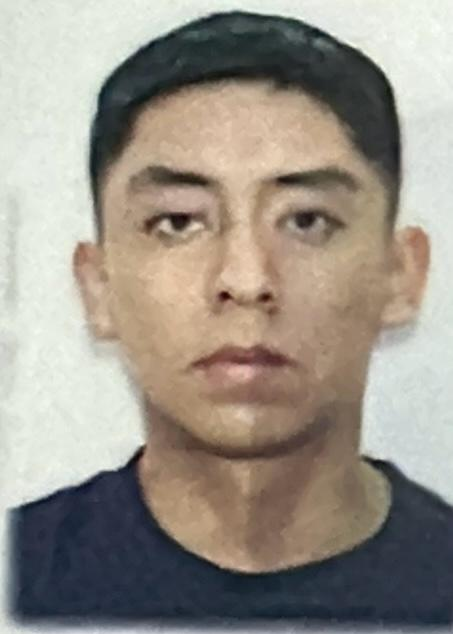

**Reporte: Planeación de Trayectorias mediante Pure Pursuit**

**Evaluación 9: Planeación de trayectorias**

**Objetivo**

Obtener un recorrido de trayectorias a partir de la forma del rostro, utilizando puntos marcados con Geogebra como referencia visual y empleando un algoritmo de seguimiento eficiente mediante la estrategia de control "Pure Pursuit".

**1. Captura y Extracción de Puntos**

Se capturó una fotografía del rostro del alumno y se graficó manualmente con el software Geogebra, identificando los puntos característicos que conforman los rasgos faciales como:

- Forma del rostro (mandíbula, barbilla y frente)

- Cabello

- Cejas

- Ojos

- Nariz

- Boca

- Orejas

Los puntos fueron extraídos en forma de coordenadas (x, y) y organizados en un arreglo secuencial denominado `waypoints`. Este mapa completo de puntos describe la forma general del rostro.

**2. Estrategia de Control Elegida: Pure Pursuit**

La técnica elegida para esta aplicación fue **Pure Pursuit** debido a las siguientes razones:

- **Adaptabilidad a curvas complejas**: Pure Pursuit se basa en una geometría sencilla que permite al robot girar hacia un punto más adelante de su posición actual (lookahead point). Esto lo hace ideal para seguir trayectorias curvas como los contornos de un rostro.

- **Robustez ante cambios de orientación**: A diferencia de un control proporcional estático, Pure Pursuit ajusta continuamente la orientación del robot para que se alinee con el siguiente segmento de la trayectoria.

- **Implementación directa sobre waypoints**: El algoritmo trabaja directamente con una lista de puntos, lo cual fue especialmente úctil dado que el contorno facial fue representado con más de 250 puntos generados manualmente.

- **Estabilidad y suavidad en el movimiento**: La trayectoria seguida por el robot no presenta movimientos abruptos o erráticos, lo cual es importante para mantener la coherencia visual del rostro.

En esta aplicación específica, Pure Pursuit permite que el robot "dibuje" el rostro completo sin requerir una planificación compleja, utilizando parámetros ajustables como la distancia de anticipación y la velocidad lineal para adaptar su comportamiento a la forma del contorno.

**3. Implementación en MATLAB**

Se utilizó el modelo de robot diferencial con la siguiente configuración:

- Radio de rueda: `R = 0.1 m`

- Distancia entre ruedas: `L = 0.5 m`

- Tiempo de muestreo: `sampleTime = 0.005 s`

- Tiempo total de simulación: `t = 335 s`

- Velocidad lineal deseada: `1.0 m/s`

- Velocidad angular máxima: `3.15 rad/s`

- Distancia de anticipación (lookahead): `0.1 m`

El algoritmo Pure Pursuit fue implementado mediante el objeto `controllerPurePursuit` en MATLAB. El controlador recibe como entrada la pose actual del robot (x, y, θ) y genera referencias de velocidad lineal `vRef` y angular `wRef` para alcanzar el siguiente punto objetivo en la trayectoria.

Estas referencias se transforman en velocidades de rueda izquierda y derecha usando cinemática inversa, y se integran con el modelo de robot diferencial para actualizar la posición. Todo el proceso se ejecuta en un ciclo de simulación con actualización visual en tiempo real.

**4. Resultado Final**

Se obtuvo una simulación precisa en la cual el robot recorrió exitosamente la trayectoria compuesta por los puntos que describen mi rostro. El resultado visual muestra claramente que el contorno generado es altamente similar a la imagen de referencia.

**Características observadas en los resultados:**

- **Rasgos faciales bien definidos (por lo menos a un 80% de semejanza)**: Las cejas, nariz, labios y contorno de la cara se representaron con buena fidelidad. Aunque objetos muy pequenos como la pupila fueron cosas que no se pudieron representar.

- **Transiciones suaves**: El algoritmo evitó giros bruscos, generando una curva continua en todo el recorrido.

- **Preservación de proporciones**: La escala del trazo es proporcional al rostro original, lo cual demuestra una adecuada elección de velocidades y de la distancia de anticipación.

Se utilizaron un total de más de 250 puntos distribuidos entre 10 grupos (de A hasta E10) para lograr una alta resolución del dibujo facial. En la visualización final se observan los detalles del peinado, ojos y forma del rostro con un trazo claro y continuo.

.**5. Conclusión**

La estrategia Pure Pursuit demostró ser altamente eficaz para el seguimiento de trayectorias derivadas de formas complejas como el contorno de un rostro humano. Su implementación fue sencilla en MATLAB, y gracias a su naturaleza basada en waypoints, se adaptó perfectamente al problema.

El comportamiento del robot fue estable, preciso y suave durante todo el recorrido. Se logró una representación visual que guarda alta similitud con la fotol.Esta experiencia permite concluir que Pure Pursuit es una herramienta poderosa y versátil para aplicaciones de trazado personalizado basadas en datos visuales.